# Inputs

T = 1200; % Sample time
Ts = 10; % Points number

Pmax = 1500;
Pmid = 1250;
Pcruise = 900;

# Flight scheme with noise

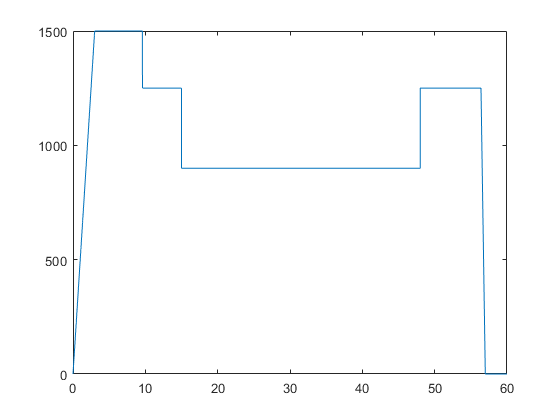

T1 = 5/100*T;
T2 = 1/100*T;
T3 = 10/100*T;
T4 = 9/100*T;
T5 = 55/100*T;
T6 = 14/100*T;
T7 = 1/100*T;
T8 = 5/100*T;

% take off + climb
F1 = linspace(0,Pmax,T1*Ts);
F2 = linspace(Pmax,Pmax,T2*Ts);
a = [F1 F2];

% max power + cruise
F3 = linspace(Pmax,Pmax,T3*Ts);
F4 = linspace(Pmid,Pmid,T4*Ts);
F5 = linspace(Pcruise,Pcruise,T5*Ts);
b = [F3 F4 F5];

% descend + landing
F6 = linspace(Pmid,Pmid,T6*Ts);
F7 = linspace(Pmid,0,T7*Ts);
F8 = linspace(0,0,T8*Ts);
c = [F6 F7 F8];


clf;
one_c = [a b c];
t_one_c = linspace(0,60,length(one_c));
load_oc_without_noise = [t_one_c; one_c];
plot(t_one_c,one_c);

% plot(load_oc_without_noise);
% save('load_oc_without_noise.mat',"load_oc_without_noise")

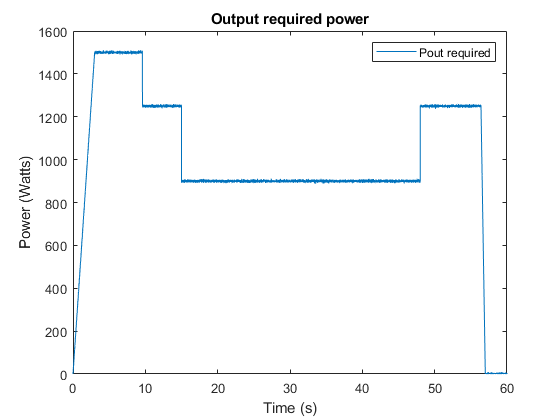

% With noise
t_one_c_bis = t_one_c;
one_c_bis = awgn(one_c,50,'measured');
plot(t_one_c,one_c_bis);
legend('Pout required');
title('Output required power');
ylabel('Power (Watts)');
xlabel('Time (s)');
ylim([0 1600]);

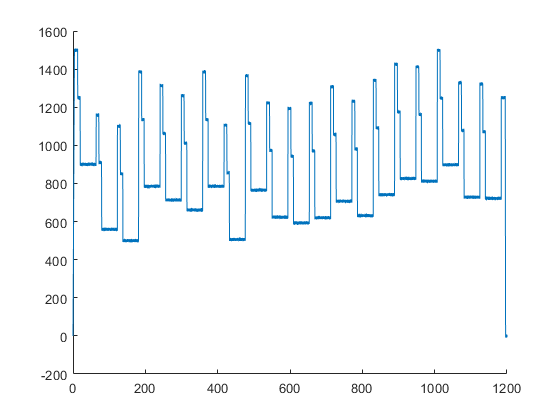



cycle = 20;
temp = [a b];
for i=1:cycle-1
    temp = [temp b+ randi([-400 0])];
end
temp = [temp c];
c_repeated = awgn(temp,50,'measured');



t_repeated = linspace(0,T,length(c_repeated));

clf;
% plot(t,x)
hold on;
plot(t_repeated,c_repeated)


save('load_oc_without_noise.mat','t_one_c','one_c','t_one_c_bis','one_c_bis','t_repeated','c_repeated')
% save(strcat(fileparts(pwd),'\data.mat'),'one_c','t_one_c','w','t')